# Generating an action potential with NEURON in MATLAB

In this example...

% Initialization & reset.
clear;
setup_nrn_paths;
n = neuron.Neuron();
n.reset_sections();

% Make axon.
axon = n.Section("axon");
axon.nseg = 3;
axon.set_diameter(50);
axon.insert_mechanism("hh");

% Connect branch.
branch = n.Section("branch1");
branch.set_diameter(10);
branch.nseg = 4;
branch.length = 1000;
branch.connect(0, axon, 1);
n.topology();

|---|       axon(0-1)
     `---|       branch1(0-1)



% Track time with Vector t_vec.
t_vec = n.Vector();
t = n.ref("t");
t_vec.record(t);

% Track voltage at two points.
v1_vec = n.Vector();
v1 = axon.ref("v", 0.5);
v1_vec.record(v1);
v2_vec = n.Vector();
v2 = branch.ref("v", 1);
v2_vec.record(v2);

% Insert current at start of axon.
iclamp = n.IClamp(axon, 0);
iclamp.del = 0.5;
iclamp.dur = 1;
iclamp.amp = 50;

% Run simulation.
n.finitialize(-65);
while n.t < 7
    n.fadvance();
end

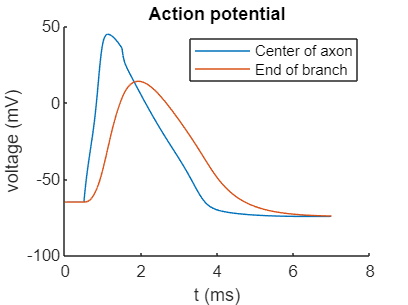

% Plot results.
figure;
hold on;
plot(t_vec, v1_vec);
plot(t_vec, v2_vec);
legend('Center of axon', 'End of branch')
title("Action potential");
xlabel("t (ms)");
ylabel("voltage (mV)");
hold off;